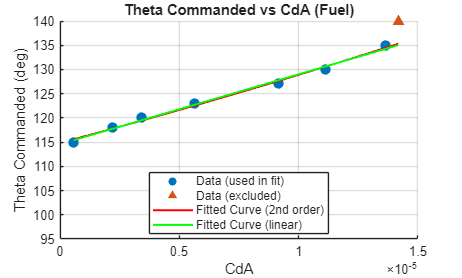

% FUEL EREG
fuelClose = 95;
fuelOpen = 140;
fuelCracking = 108;

thetaCommandedArray     = [115 118 120 123 127 130 135 140];
upstreamPressureArray   = [6.78 6.17 5.55 4.53 3.59 3.76 3.19 3.57] * 1e5;
downstreamPressureArray = [1.03 1.21 1.40 1.74 2.04 2.38 2.31 2.59] * 1e5;
mdotArray               = [0.0195 0.0691 0.0981 0.1336 0.1611 0.1845 0.1810 0.1984];

nFitPoints = numel(thetaCommandedArray) - 1;  % exclude final point from fitting only

relationStructFuel = struct('thetaCommanded', {}, 'thetaPercentage', {}, 'dP', {}, 'CdA', {}, 'Kv', {});

for i = 1:numel(thetaCommandedArray)
    thetaCommanded      = thetaCommandedArray(i);
    upstreamPressure    = upstreamPressureArray(i);
    downstreamPressure  = downstreamPressureArray(i);
    mdot                = mdotArray(i);

    CdA = getCdAfromData(upstreamPressure, downstreamPressure, mdot, 1000);
    Kv  = CdA * 50900;
    thetaPercentage = (thetaCommanded - fuelClose) * 100 / (fuelOpen - fuelClose);
    dP = upstreamPressure - downstreamPressure;
    dP = dP * 1e-05;
    relationStructFuel(i) = struct('thetaCommanded', thetaCommanded, ...
                                'thetaPercentage', thetaPercentage, ...
                                'dP', dP,...
                                'CdA', CdA, ...
                                'Kv', Kv);
end

save('CdARelationship.mat', 'relationStructFuel');

allThetaPercentages = [relationStructFuel.thetaPercentage];
allAngles = [relationStructFuel.thetaCommanded];
allCdA = [relationStructFuel.CdA];
allKvs = [relationStructFuel.Kv];

% Fit only on the first nFitPoints, excluding the last point
quadraticFitFuel = polyfit(allCdA(1:nFitPoints), allAngles(1:nFitPoints), 2);
linearFitFuel = polyfit(allCdA(1:nFitPoints), allAngles(1:nFitPoints), 1);
linearFitFuelKv = polyfit(allKvs(1:nFitPoints), allAngles(1:nFitPoints), 1);

% Plot collected data points (CdA on x, theta on y)
figure;
scatter(allCdA(1:nFitPoints), allAngles(1:nFitPoints), 60, 'filled', 'MarkerFaceColor', [0 0.4470 0.7410]);
hold on;
scatter(allCdA(end), allAngles(end), 60, 'filled', 'Marker', '^', 'MarkerFaceColor', [0.8500 0.3250 0.0980]);

% Evaluate both fitted curves over the CdA data range (all points, including excluded one)
CdAFit = linspace(min(allCdA), max(allCdA), 500);
thetaFitQuad = polyval(quadraticFitFuel, CdAFit);
thetaFitLinear = polyval(linearFitFuel, CdAFit);

plot(CdAFit, thetaFitQuad, 'r-', 'LineWidth', 1.5);
plot(CdAFit, thetaFitLinear, 'g-', 'LineWidth', 1.5);

xlabel('CdA');
ylabel('Theta Commanded (deg)');
title('Theta Commanded vs CdA (Fuel)');
legend('Data (used in fit)', 'Data (excluded)', 'Fitted Curve (2nd order)', 'Fitted Curve (linear)', 'Location', 'best');
grid on;
ylim([fuelClose fuelOpen]);
hold off;

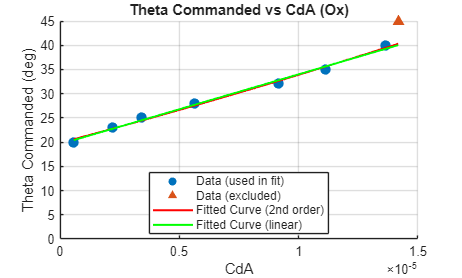


% EXPECTED OX EREG RELATIONSHIP
oxClose = 0;
oxOpen = 45;
oxCracking = 13;

commandDiff = oxClose - fuelClose;
thetaCommandedArray = thetaCommandedArray + commandDiff;

relationStructOx = struct('thetaCommanded', {}, 'thetaPercentage', {}, 'dP', {}, 'CdA', {}, 'Kv', {});

for i = 1:numel(thetaCommandedArray)
    thetaCommanded      = thetaCommandedArray(i);
    upstreamPressure    = upstreamPressureArray(i);
    downstreamPressure  = downstreamPressureArray(i);
    mdot                = mdotArray(i);

    CdA = getCdAfromData(upstreamPressure, downstreamPressure, mdot, 1000);
    Kv  = CdA * 50900;
    thetaPercentage = (thetaCommanded - oxClose) * 100 / (oxOpen - oxClose);
    dP = upstreamPressure - downstreamPressure;
    dP = dP * 1e-05;
    relationStructOx(i) = struct('thetaCommanded', thetaCommanded, ...
                                'thetaPercentage', thetaPercentage, ...
                                'dP', dP,...
                                'CdA', CdA, ...
                                'Kv', Kv);
end

save('CdARelationship.mat', 'relationStructOx', '-append');

allThetaPercentages = [relationStructOx.thetaPercentage];
allAngles = [relationStructOx.thetaCommanded];
allCdA = [relationStructOx.CdA];
allKvs = [relationStructOx.Kv];

quadraticFitOx = polyfit(allCdA(1:nFitPoints), allAngles(1:nFitPoints), 2);
linearFitOx = polyfit(allCdA(1:nFitPoints), allAngles(1:nFitPoints), 1);
linearFitOxKv = polyfit(allKvs(1:nFitPoints), allAngles(1:nFitPoints), 1);
figure;
scatter(allCdA(1:nFitPoints), allAngles(1:nFitPoints), 60, 'filled', 'MarkerFaceColor', [0 0.4470 0.7410]);
hold on;
scatter(allCdA(end), allAngles(end), 60, 'filled', 'Marker', '^', 'MarkerFaceColor', [0.8500 0.3250 0.0980]);

CdAFit = linspace(min(allCdA), max(allCdA), 500);
thetaFitQuad = polyval(quadraticFitOx, CdAFit);
thetaFitLinear = polyval(linearFitOx, CdAFit);

plot(CdAFit, thetaFitQuad, 'r-', 'LineWidth', 1.5);
plot(CdAFit, thetaFitLinear, 'g-', 'LineWidth', 1.5);

xlabel('CdA');
ylabel('Theta Commanded (deg)');
title('Theta Commanded vs CdA (Ox)');
legend('Data (used in fit)', 'Data (excluded)', 'Fitted Curve (2nd order)', 'Fitted Curve (linear)', 'Location', 'best');
grid on;
ylim([oxClose oxOpen]);
hold off;